#  Homework 4: RRP Robot

%Mostafa Osama Ahmed
%Innopolis University - DoNRS course
clear all
close all


Github Link: 

[https://github.com/mostafa-metwaly/DoNRs-HW4](https://github.com/mostafa-metwaly/DoNRs-HW4)

q1, q2, d3 are joint space variables, px, py, pz are operational space variables and Parameters

d1, a2 are known

% set angles and links as symbolical
syms d1 a2 d3 q1 q2 r s Px Py Pz
% d1=1
% a2=1

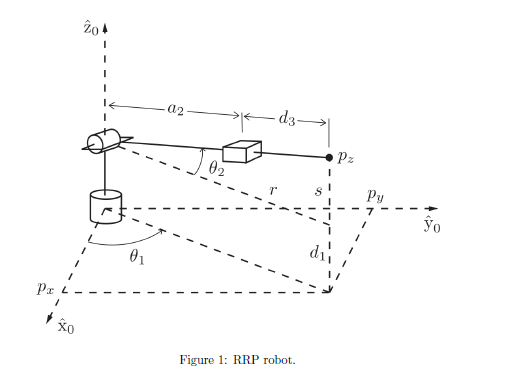

## 1.Forward Kinematics


$$H=R_z \left(\textrm{q1}\right)\cdot T_z \left(\textrm{d1}\right)\cdot R_y \left(\textrm{q2}\right)\cdot T_x \left(\textrm{a2}\right)\cdot T_x \left(\textrm{d3}\right)$$


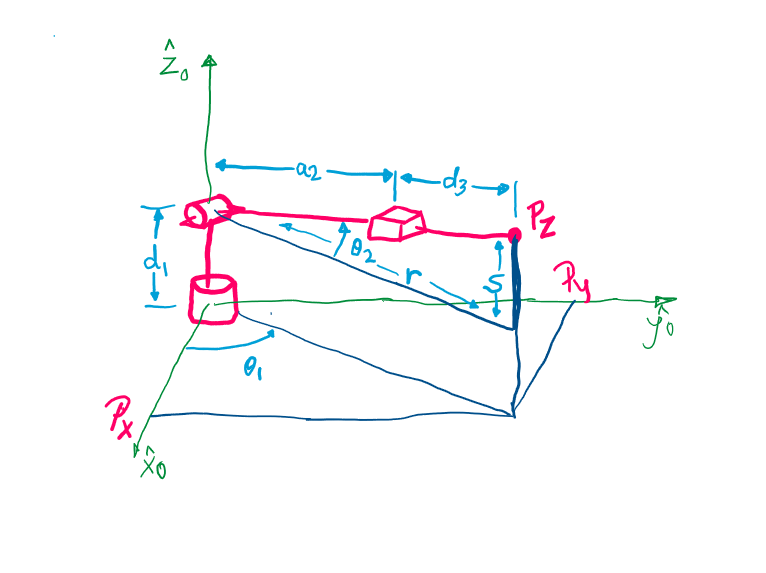

% forward kinematics
H = simplify(Rz(q1)*Tz(d1)*Ry(-q2)*Tx(a2)*Tx(d3))

$$H = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(a_{2}+d_{3}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(a_{2}+d_{3}\right)\\ \sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & d_{1}+a_{2}\,\sin\left(q_{2}\right)+d_{3}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% extract rotation matrix
R = simplify(H(1:3,1:3))

$$R = \left(\begin{array}{ccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) \end{array}\right)$$

Px and Py depends on the value of r :

Px=r*cos(q1) ,  Py=r*sin(q1)

and r=(a2+d3)*cos(q2)

where for Pz value depends on s :

Pz=d1+s   ,  s=(a2+d3)*sin(q2)

Position of the End effector for RRP robot in operational space variables.can be described by the vector T

$\left\lbrack \begin{array}{c}
\textrm{Px}\\
\textrm{Py}\\
\textrm{Pz}
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{c}
r\;\cos \left(\textrm{q1}\right)\\
r\;\sin \left(\textrm{q1}\right)\\
\textrm{d1}+s
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{c}
\cos \left(q_1 \right)\,\cos \left(q_2 \right)\,{\left(a_2 +d_3 \right)}\\
\cos \left(q_2 \right)\,\sin \left(q_1 \right)\,{\left(a_2 +d_3 \right)}\\
d_1 +a_2 \,\sin \left(q_2 \right)+d_3 \,\sin \left(q_2 \right)
\end{array}\right\rbrack$

T = simplify(H(1:3,4))

$$T = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(a_{2}+d_{3}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(a_{2}+d_{3}\right)\\ d_{1}+a_{2}\,\sin\left(q_{2}\right)+d_{3}\,\sin\left(q_{2}\right) \end{array}\right)$$

Px=T(1,1); 
Py=T(2,1); 
Pz=T(3,1);

## 2. Inverse Kinematics

The robot has 3 joints 2 revolute and one prismatic

Px Py Pz - sets the position of EE we have already calculated it from vector T

q1 q2 d3 - sets the orientation of EE

there are only 2 solutions for solving this q1 and another 2 solutions for q2 and d3 can be found with one way the positive value where we neglected the negative value.

since we know vector T we can callculate the angles:

q1: 

    q11=atan2(Px,Py)       or       q12=  $\pi$ + atan2(Px,Py)

disp('q1, 1st solution')

q1, 1st solution


q11=simplify(atan2(Py,Px))

$$q11 = \text{angle}\left(\cos\left(q_{2}\right)\,\left(a_{2}+d_{3}\right)\,\left(\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\,\mathrm{i}\right)\right)$$


disp('q1, 2nd solution')

q1, 2nd solution


q12=simplify(pi+atan2(Py,Px))

$$q12 = \pi +\text{angle}\left(\cos\left(q_{2}\right)\,\left(a_{2}+d_{3}\right)\,\left(\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\,\mathrm{i}\right)\right)$$

we then could get the values of s, r :

$r=\sqrt{{\mathrm{Px}}^2 +{\mathrm{Py}}^2 }$     and     $s=\mathrm{Pz}-\mathrm{d1}$

q2: 

    q21=$\frac{\pi }{2}$+atan2(s,r)       or       q22= $\frac{3\;\pi }{2}$- atan2(s,r)

r=simplify(sqrt(Px^2+Py^2))

$$r = \sqrt{-{\left(a_{2}+d_{3}\right)}^{2}\,\left({\sin\left(q_{2}\right)}^{2}-1\right)}$$

s=simplify(Pz-d1)

$$s = \sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right)$$


disp('q2, for the 1st solution')

q2, for the 1st solution


q21=simplify((pi/2)+atan2(s,r))

$$q21 = \frac{\pi }{2}+\text{atan2}\left(\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right),\sqrt{-{\left(a_{2}+d_{3}\right)}^{2}\,\left({\sin\left(q_{2}\right)}^{2}-1\right)}\right)$$


disp('q2, for the 2nd solution')

q2, for the 2nd solution


q22=simplify((3*pi/2)-atan2(s,r))

$$q22 = \frac{3\,\pi }{2}-\text{atan2}\left(\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right),\sqrt{-{\left(a_{2}+d_{3}\right)}^{2}\,\left({\sin\left(q_{2}\right)}^{2}-1\right)}\right)$$

d3 can be found by:


$$\mathrm{d3}=\sqrt{r^2 +s^2 }-\mathrm{a2}$$


disp('q3, same for both solutions')

q3, same for both solutions


d3=simplify(sqrt(r^2+s^2)-a2)

$$d3 = \sqrt{{\left(a_{2}+d_{3}\right)}^{2}}-a_{2}$$

**Orientation**

$q=\left\lbrack \begin{array}{c}
\textrm{q1}\\
\textrm{q2}\\
\textrm{d3}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{atan2}\left(\textrm{Py},\textrm{Px}\right)\\
\frac{\pi }{2}+\textrm{atan2}\left(s,r\right)\\
\sqrt{r^2 +s^2 }-\textrm{a2}
\end{array}\right\rbrack \;\;\;$  or   $q=\left\lbrack \begin{array}{c}
\textrm{q1}\\
\textrm{q2}\\
\textrm{d3}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\pi +\textrm{atan2}\left(\textrm{Py},\textrm{Px}\right)\\
\frac{3\pi }{2}-\textrm{atan2}\left(s,r\right)\\
\sqrt{r^2 +s^2 }-\textrm{a2}
\end{array}\right\rbrack \;\;\;$

q_1=[q11 q12 d3]

$$q\_1 = \left(\begin{array}{ccc} \text{angle}\left(\cos\left(q_{2}\right)\,\left(a_{2}+d_{3}\right)\,\left(\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\,\mathrm{i}\right)\right) & \pi +\text{angle}\left(\cos\left(q_{2}\right)\,\left(a_{2}+d_{3}\right)\,\left(\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\,\mathrm{i}\right)\right) & \sqrt{{\left(a_{2}+d_{3}\right)}^{2}}-a_{2} \end{array}\right)$$

q_2=[q21 q22 d3]

$$q\_2 = \left(\begin{array}{ccc} \frac{\pi }{2}+\text{atan2}\left(\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right),\sqrt{-{\left(a_{2}+d_{3}\right)}^{2}\,\left({\sin\left(q_{2}\right)}^{2}-1\right)}\right) & \frac{3\,\pi }{2}-\text{atan2}\left(\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right),\sqrt{-{\left(a_{2}+d_{3}\right)}^{2}\,\left({\sin\left(q_{2}\right)}^{2}-1\right)}\right) & \sqrt{{\left(a_{2}+d_{3}\right)}^{2}}-a_{2} \end{array}\right)$$

q=[q1 ; q2]

$$q = \left(\begin{array}{c} q_{1}\\ q_{2} \end{array}\right)$$

syms q1 q2 d3 a2 d1
checking1=simplify(subs(q_1,{d1,a2,q1,q2,d3},{1,1,pi,pi,2}))

$$checking1 = \left(\begin{array}{ccc} 0 & \pi & 2 \end{array}\right)$$

checking2=simplify(subs(q_2,{d1,a2,q1,q2,d3},{1,1,pi,pi,2}))

$$checking2 = \left(\begin{array}{ccc} \frac{\pi }{2} & \frac{3\,\pi }{2} & 2 \end{array}\right)$$

## 3. Jacobian

### Classical approach

the 6-vector consisting of the linear and angular velocities of the end-effector


$$\left\lbrack \begin{array}{c}
\overset{\bullet }{P_x } \\
\overset{\bullet }{P_y } \\
\overset{\bullet }{P_z } \\
\overset{\bullet }{\omega_X } \\
\overset{\bullet }{\omega_X } \\
\overset{\bullet }{\omega_X } 
\end{array}\right\rbrack$$


Jacobian equal the partial derivative of vector T wrt each of the q1,q2,d3


$$J=\left\lbrack \begin{array}{c}
J_{\upsilon } \\
J_{\omega } 
\end{array}\right\rbrack$$


we have calculated the linearJacobian part $J_{\upsilon }$


$$J_{\upsilon } =\left\lbrack \begin{array}{ccc}
\delta \textrm{Px}/\delta \textrm{q1} & \delta \textrm{Px}/\delta \textrm{q2} & \delta \textrm{Px}/\delta \textrm{d3}\\
\delta \textrm{Py}/\delta \textrm{q1} & \delta \textrm{Py}/\delta \textrm{q2} & \delta \textrm{Py}/\delta \textrm{d3}\\
\delta \textrm{Pz}/\delta \textrm{q1} & \delta \textrm{Pz}/\delta \textrm{q2} & \delta \textrm{Pz}/\delta \textrm{d3}
\end{array}\right\rbrack$$


syms d1 a2 d3 q1 q2 r s Px Py Pz real

J1=diff(T,q1)

$$J1 = \left(\begin{array}{c} -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(a_{2}+d_{3}\right)\\ \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(a_{2}+d_{3}\right)\\ 0 \end{array}\right)$$

J2=diff(T,q2)

$$J2 = \left(\begin{array}{c} -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right)\\ -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right)\\ a_{2}\,\cos\left(q_{2}\right)+d_{3}\,\cos\left(q_{2}\right) \end{array}\right)$$

J3=diff(T,d3)

$$J3 = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sin\left(q_{2}\right) \end{array}\right)$$


Jw = [0, -sin(q1), 0;
      0, cos(q1), 0;
      1, 0, 0];
Jq1 = [simplify(J1), simplify(-J2), simplify(J3) ; Jw]

$$Jq1 = \left(\begin{array}{ccc} -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 0 & -\cos\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \sin\left(q_{2}\right)\\ 0 & -\sin\left(q_{1}\right) & 0\\ 0 & \cos\left(q_{1}\right) & 0\\ 1 & 0 & 0 \end{array}\right)$$

### Skew theory 

or geometric approach

First find origin of each joint

FK:


T00= eye(4)

T00 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T01= Rz(q1)*Tz(d1)

$$T01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T02= Rz(q1)*Tz(d1)*Ry(-q2)

$$T02 = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & 0\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & 0\\ \sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T03= Rz(q1)*Tz(d1)*Ry(-q2)*Tx(a2)*Tx(d3)

$$T03 = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & a_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+d_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & a_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+d_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & d_{1}+a_{2}\,\sin\left(q_{2}\right)+d_{3}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Origins as position component of FK

O0 = T00(1:3,4)

O0 =      0
     0
     0


O1 = T01(1:3,4)

$$O1 = \left(\begin{array}{c} 0\\ 0\\ d_{1} \end{array}\right)$$

O2 = T02(1:3,4)

$$O2 = \left(\begin{array}{c} 0\\ 0\\ d_{1} \end{array}\right)$$

O3 = T03(1:3,4)

$$O3 = \left(\begin{array}{c} a_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+d_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ a_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+d_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ d_{1}+a_{2}\,\sin\left(q_{2}\right)+d_{3}\,\sin\left(q_{2}\right) \end{array}\right)$$

Find rotation (translation in case of prismatic joint) axis Z from transformation, note the coloumn! Its should correspond to the joint axis

Z0 = T00(1:3,3) % 3rd coloumn corresponds to Rz

Z0 =      0
     0
     1


Z1 = T01(1:3,2) % 2nd coloumn corresponds to Ry

$$Z1 = \left(\begin{array}{c} -\sin\left(q_{1}\right)\\ \cos\left(q_{1}\right)\\ 0 \end{array}\right)$$

Z2 = T02(1:3,1) % 1st coloumn corresponds to Tx

$$Z2 = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sin\left(q_{2}\right) \end{array}\right)$$

Full Jacobian

for revolute joint:


$$J_i =\left\lbrack \begin{array}{c}
Z_{i-1} \times \left(O_n -O_{i-1} \right)\\
Z_{i-1} 
\end{array}\right\rbrack$$


for prismatic joint:


$$J_i =\left\lbrack \begin{array}{c}
Z_{i-1} \\
0
\end{array}\right\rbrack$$


J1 = [cross(Z0,(O3-O0));Z0];
J2 = [cross(Z1,(O3-O1));Z1];
J3 = [Z2;0; 0; 0];


Jq2 = [simplify(J1), simplify(J2), simplify(J3)]

$$Jq2 = \left(\begin{array}{ccc} -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 0 & -\cos\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \sin\left(q_{2}\right)\\ 0 & -\sin\left(q_{1}\right) & 0\\ 0 & \cos\left(q_{1}\right) & 0\\ 1 & 0 & 0 \end{array}\right)$$

### **Numerical derivatives**


%Same could be done for other Jacobian columns
% forward kinematics
H = Rz(q1)*Tz(d1)*Ry(-q2)*Tx(a2)*Tx(d3);
H=simplify(H);
% extract rotation matrix
R = simplify(H(1:3,1:3));
% diff by q1
Td= Rzd(q1)*Tz(d1)*Ry(-q2)*Tx(a2)*Tx(d3)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 1st column
J1 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' 

$$J1 = \begin{array}{l} \left(\begin{array}{c} -a_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-d_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ a_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+d_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ 0\\ 0\\ 0\\ \frac{{\sin\left(q_{1}\right)}^{2}}{{\cos\left(q_{1}\right)}^{2}+{\sin\left(q_{1}\right)}^{2}}+\frac{\sigma_{3}}{\sigma_{1}}+\frac{\sigma_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{3}+\sigma_{2}+{\cos\left(q_{2}\right)}^{2}\,{\sin\left(q_{1}\right)}^{2}+{\sin\left(q_{1}\right)}^{2}\,{\sin\left(q_{2}\right)}^{2}\\ \sigma_{2}={\cos\left(q_{1}\right)}^{2}\,{\sin\left(q_{2}\right)}^{2}\\ \sigma_{3}={\cos\left(q_{1}\right)}^{2}\,{\cos\left(q_{2}\right)}^{2} \end{array}$$

% diff by q2
Td= Rz(q1)*Tz(d1)*Ryd(-q2)*Tx(a2)*Tx(d3)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 2nd column
J2 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' 

$$J2 = \begin{array}{l} \left(\begin{array}{c} a_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+d_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ a_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)+d_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ -a_{2}\,\cos\left(q_{2}\right)-d_{3}\,\cos\left(q_{2}\right)\\ -\frac{{\cos\left(q_{2}\right)}^{2}\,\sin\left(q_{1}\right)}{\sigma_{1}}-\frac{\sin\left(q_{1}\right)\,{\sin\left(q_{2}\right)}^{2}}{\sigma_{1}}\\ \frac{\cos\left(q_{1}\right)\,{\cos\left(q_{2}\right)}^{2}}{\sigma_{2}}+\frac{\cos\left(q_{1}\right)\,{\sin\left(q_{2}\right)}^{2}}{\sigma_{2}}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\cos\left(q_{1}\right)}^{2}\,{\cos\left(q_{2}\right)}^{2}+{\cos\left(q_{1}\right)}^{2}\,{\sin\left(q_{2}\right)}^{2}+{\cos\left(q_{2}\right)}^{2}\,{\sin\left(q_{1}\right)}^{2}+{\sin\left(q_{1}\right)}^{2}\,{\sin\left(q_{2}\right)}^{2}\\ \sigma_{2}={\cos\left(q_{2}\right)}^{2}+{\sin\left(q_{2}\right)}^{2} \end{array}$$

% diff by q3
Td= Rz(q1)*Tz(d1)*Ry(-q2)*Tx(a2)*Txd(d3)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 3rd column
J3 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' 

$$J3 = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sin\left(q_{2}\right)\\ 0\\ 0\\ 0 \end{array}\right)$$


% Full Jacobian 6x6
Jq3 = [simplify(J1), simplify(J2), simplify(J3)]

$$Jq3 = \left(\begin{array}{ccc} -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 0 & -\cos\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \sin\left(q_{2}\right)\\ 0 & -\sin\left(q_{1}\right) & 0\\ 0 & \cos\left(q_{1}\right) & 0\\ 1 & 0 & 0 \end{array}\right)$$

### checking the different Jacobian methods: 

check1=simplify(Jq1-Jq2)

$$check1 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

check2=simplify(Jq1-Jq3)

$$check2 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

check3=simplify(Jq2-Jq1)

$$check3 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

check4=simplify(Jq2-Jq3)

$$check4 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

check5=simplify(Jq3-Jq1)

$$check5 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

check6=simplify(Jq3-Jq2)

$$check6 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

then all the Jacobian Methods are the same.

## 4. Singularities

for Jacobian singularity analysis we need to get the determinant of the jacobian matrix in order to estimate the case which will make the matrix equal zero and we will calculate it for the upper part which is the linear part

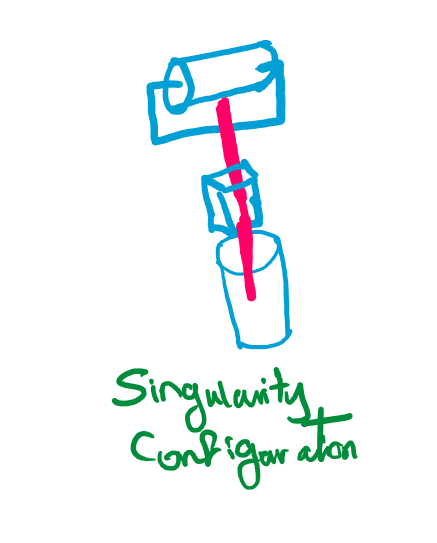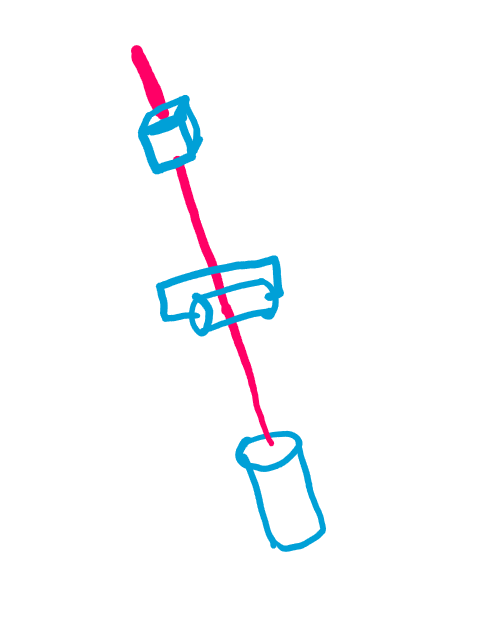

analyze1=simplify(det(Jq3(1:3,1:3)))

$$analyze1 = -\cos\left(q_{2}\right)\,{\left(a_{2}+d_{3}\right)}^{2}$$


$${\mathrm{det}\;\;\mathrm{Jq3}}_{\nu } =\mathrm{cos}\left(\mathrm{q2}\right){\;\left(\mathrm{a2}+\mathrm{d3}\right)}^2$$
 

this equation from the det of the matrix will be equal to zero in two cases only when 

when case1:  d3 = -a2 and case2:  cos(q2) = 0 

case1:

d3 can be found by:

$\mathrm{d3}=\sqrt{r^2 +s^2 }-\mathrm{a2}$   so this equation will  be equal to zero if the square root part is equal to zero that means r and s are equal to zero where

$r=\sqrt{{\textrm{Px}}^2 +{\textrm{Py}}^2 }$     and     $s=\mathrm{Pz}-\mathrm{d1}$

this could happen if Px and Py points are equal to zero which is the origin point of the robot.

case2:

when cos(q2)=0  which happens when q2 is equal to pi/2 or -pi/2 and this will reduce the number of DOF by one and the endeffector position is intersecting the Z axis and any rotation around the robot base will not affect the position of end effector.

## 5. velocity of the tool frame

joint variables are changing with time as follows:

q1(t) = sin(t); q2(t) = cos(2t); d3(t) = sin(3t)

we will subistitute in the jacobian and multiply them by the derivatives of these equations

syms q1_t q2_t d3_t t real
q1_t = sin(t); q2_t = cos(2*t); d3_t = sin(3*t);

J_t=simplify(subs(Jq3,{d1,a2,q1,q2,d3},{1,1,q1_t,q2_t,d3_t}));
q=[q1_t q2_t d3_t]';
q_dot=diff(q)

$$q\_dot = \left(\begin{array}{c} \cos\left(t\right)\\ -2\,\sin\left(2\,t\right)\\ 3\,\cos\left(3\,t\right) \end{array}\right)$$

getting there derivative:

q_1(t) = cos (t) ;  q_2(t) = -2 sin (2t) ; d_3(t) = 3 cos (3t)

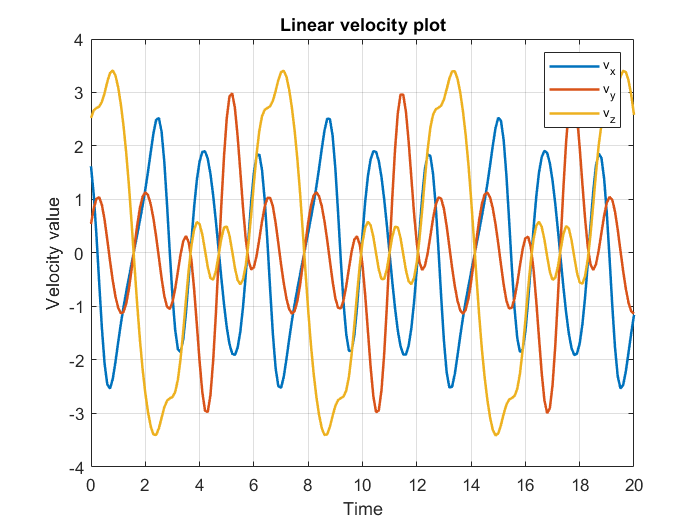

Ai= simplify(J_t*q_dot);
time=0:0.1:20;

Ai_t=subs(Ai,{t},{time});
fig=figure(1);
set(gcf,'color','w');
plot(time, Ai_t(1:3, :), 'LineWidth', 1.5)
grid on
xlabel('Time')
ylabel('Velocity value')
title('Linear velocity plot')
legend('v_x', 'v_y', 'v_z', 'Fontsize', 8)
frame = getframe(fig);

im = frame2im(frame);
[img,map] = rgb2ind(im,256);
imwrite(img,map,'linear_velocities.png','png');

Linear velocity graph is shown 

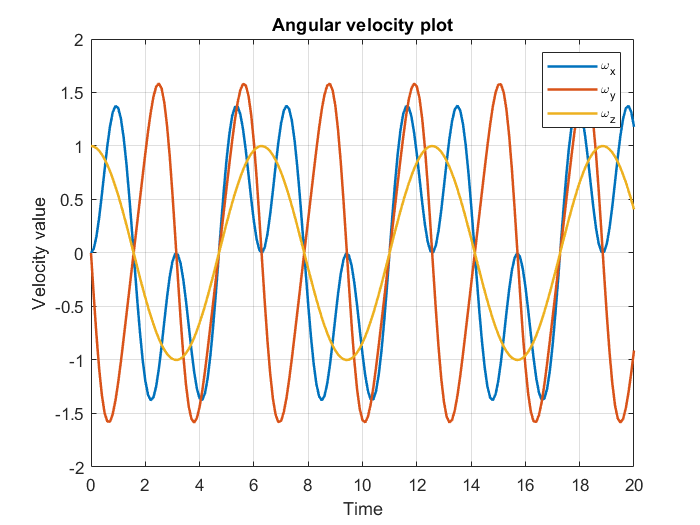

fig = figure(2);
set(gcf,'color','w');
plot(time, Ai_t(4:6, :), 'LineWidth', 1.5)
grid on
xlabel('Time')
ylabel('Velocity value')
title('Angular velocity plot')
legend('\omega_x', '\omega_y', '\omega_z', 'Fontsize', 8)
frame = getframe(fig);

im = frame2im(frame);
[img,map] = rgb2ind(im,256);
imwrite(img,map,'angular_velocities.png','png');